# Optimize Design to Reach a Target Temperature

This demo explores the cooling of a block via cooling pipes carrying water at a given mass flow rate. The top block is heated by a constant heat source, and the number of pipes and their hydraulic diameter are optimized so that a target temperature is reached but not exceeded in the block. This has applications in Electric Vehicles, for example in the design of cold plates for [battery thermal analysis](https://www.mathworks.com/help/pde/ug/reduced-order-model-for-battery-thermal-behavior.html) and [battery thermal management systems](https://www.mathworks.com/discovery/battery-thermal-management-system.html). 

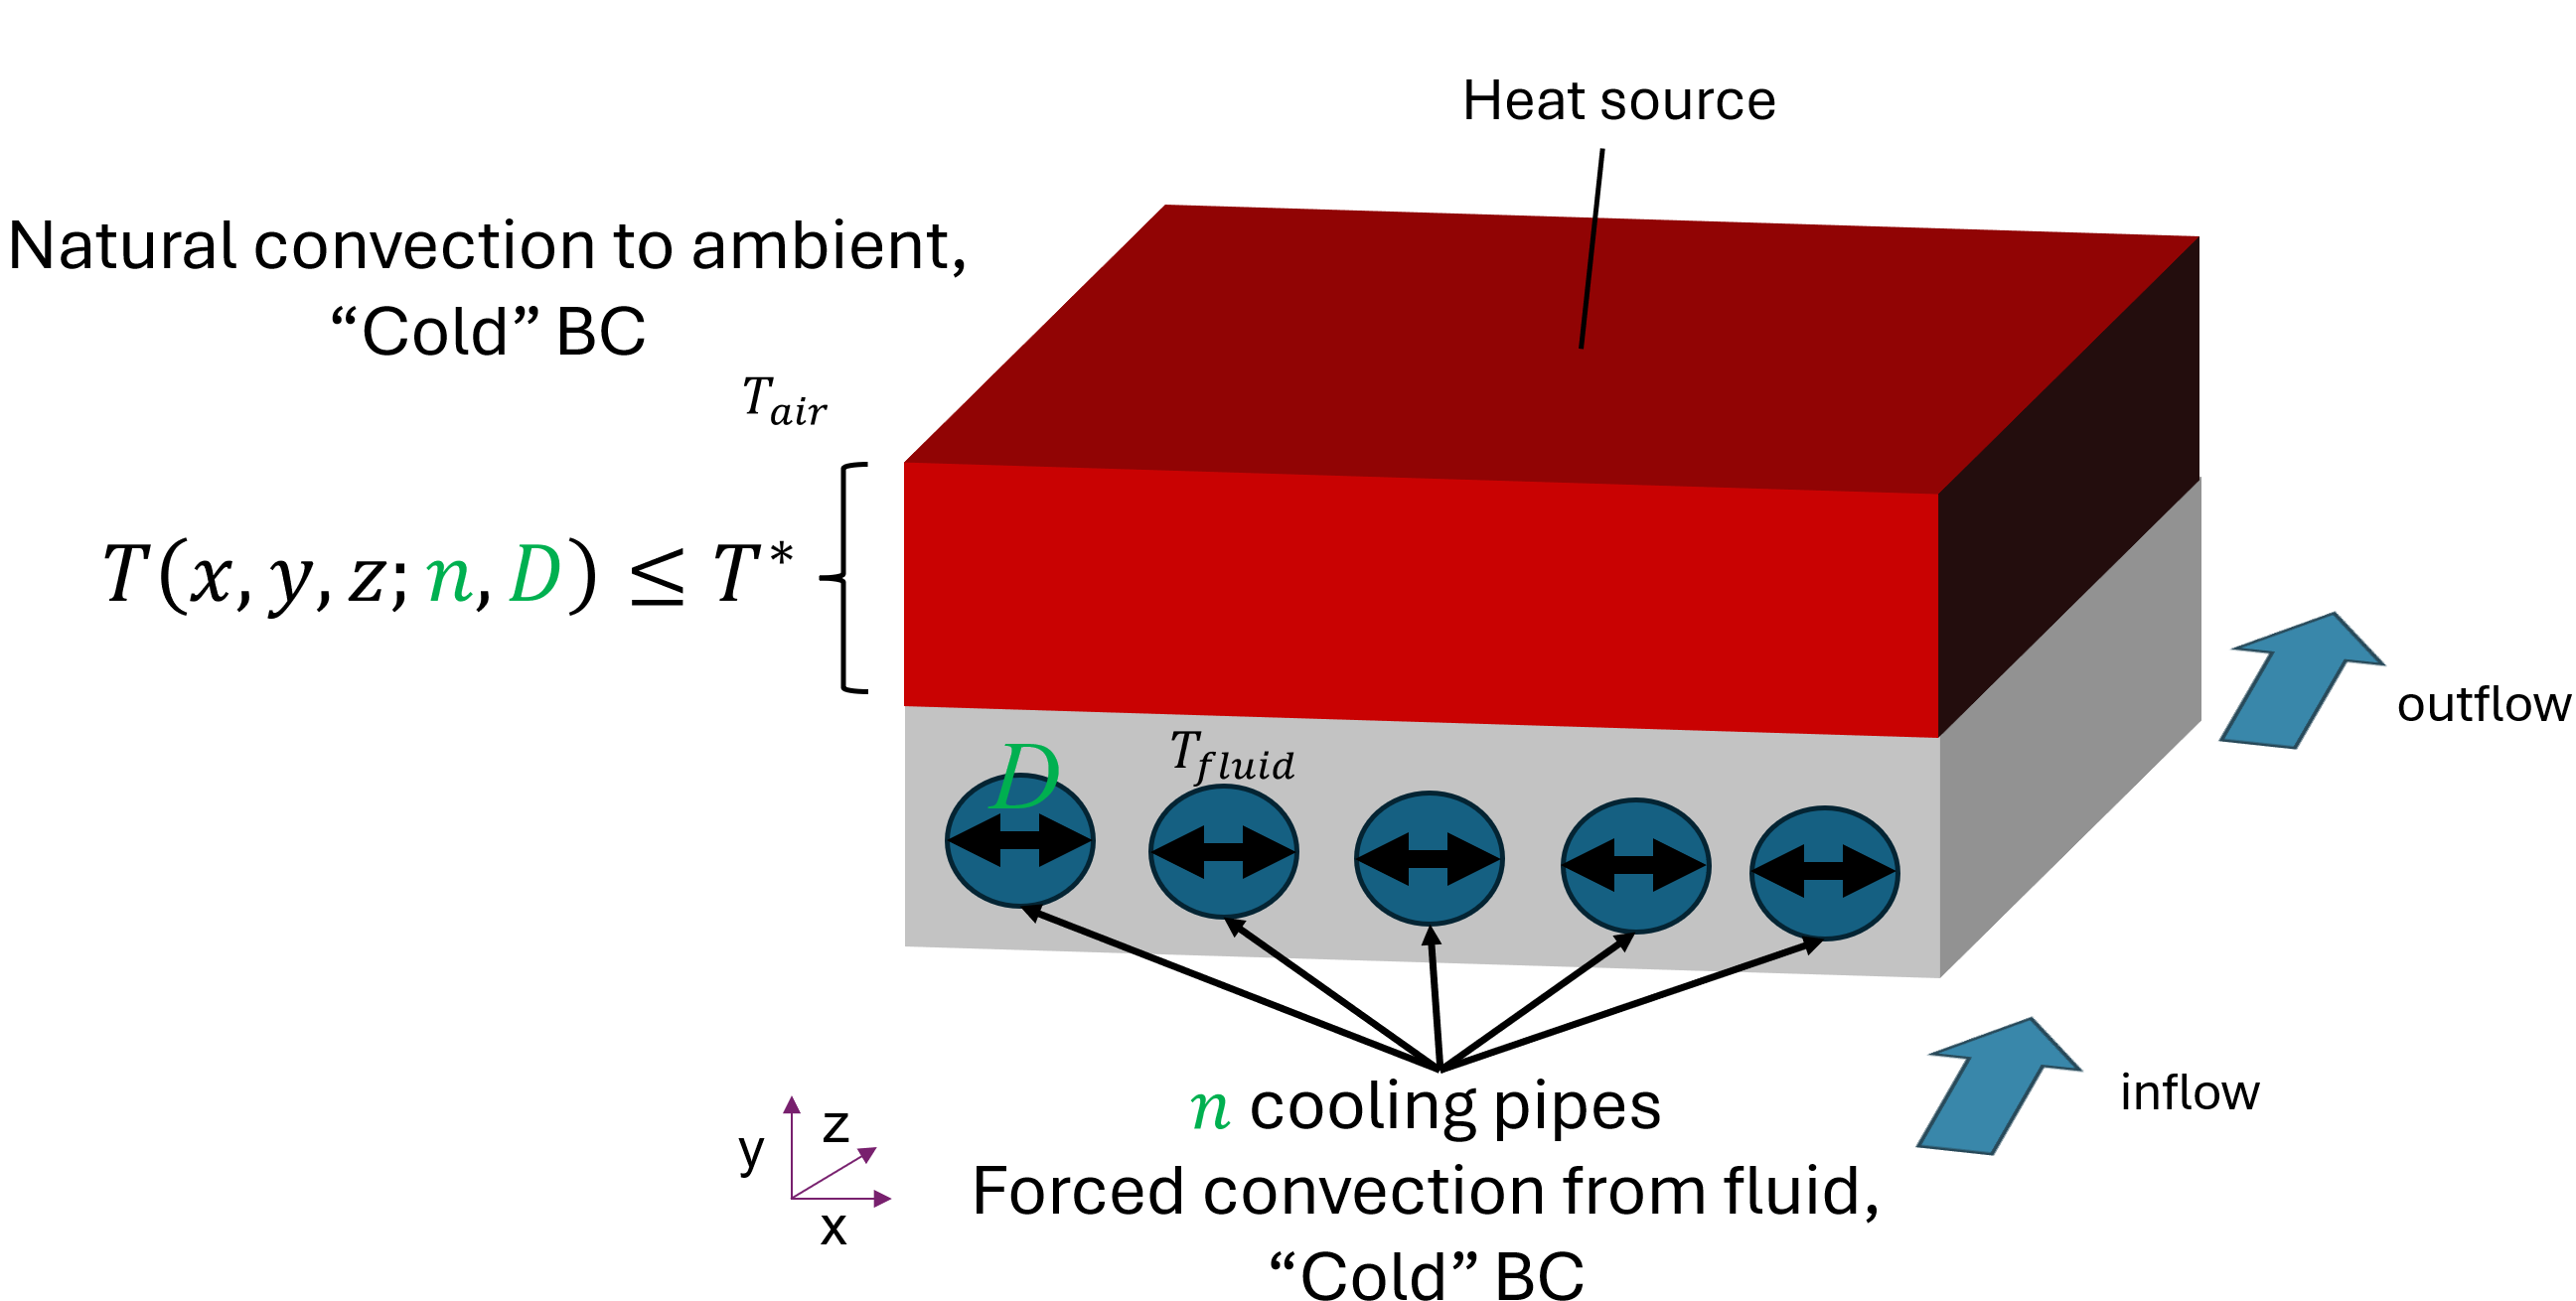

The maximum temperature in the top block is computed via a [finite element](https://www.mathworks.com/discovery/finite-element-analysis.html) simulation using [Partial Differential Equation Toolbox™](https://www.mathworks.com/products/pde.html). The optimization is conducted using [surrogate optimization](https://www.mathworks.com/help/gads/surrogate-optimization.html) from [Global Optimization Toolbox™](https://www.mathworks.com/products/global-optimization.html). 

## Problem pre-processing

Suppose our target maximum temperature in the heat-producing block is 358.15K.  

Let's investigate the block temperature without any cooling pipes. We use a helper function, `ModifyGeomRunforFEA`, which given a number of cooling pipes and pipe diameter, modifies the geometry and conducts the Finite Element Analysis (FEA). 

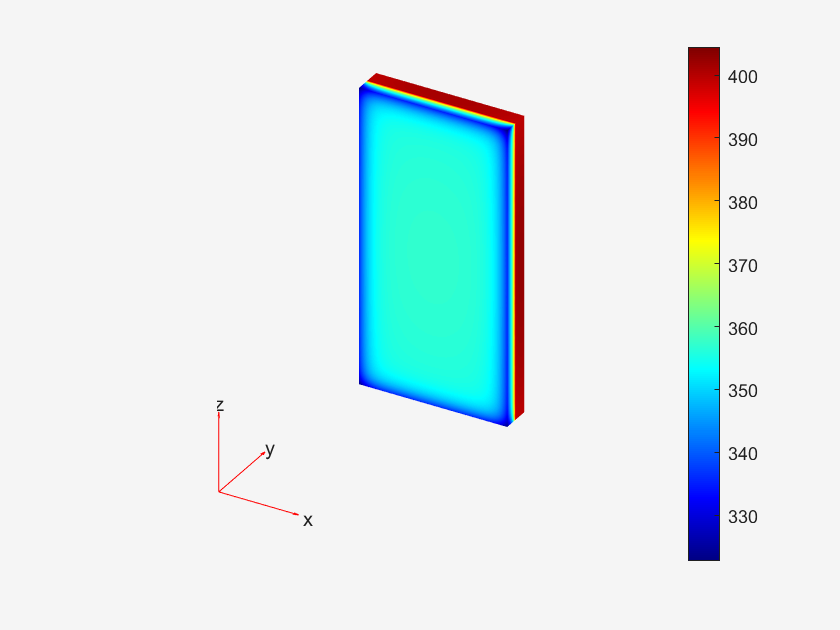

ans = 'Max temp on heat-producing block = 404.4749'

ModifyGeomRunFEAforOptim([0;1e-3],358.15,1);

If we want to get close to that target temperature, we could add cooling pipes and vary the diameter of the pipes. However, manually choosing these values and then re-running the FEA will be a very time-consuming process. 

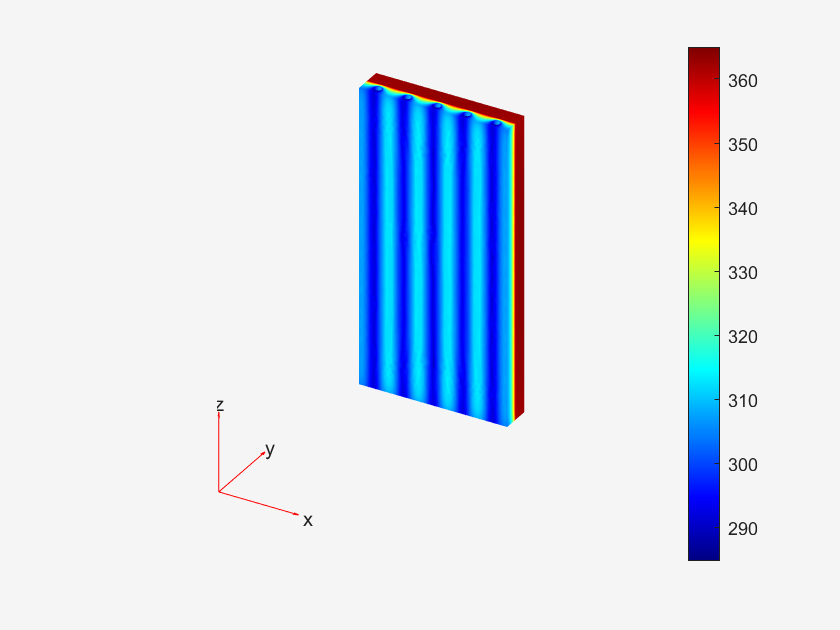

ans = 'Max temp on heat-producing block = 364.9907'

x0 = [5; 0.01];
startingGuess = ModifyGeomRunFEAforOptim(x0,358.15,1);

Instead, we can automate this process using functionality from Global Optimization Toolbox.

## Optimization Formulation

We optimize over the number of cooling pipes, $n$, and the diameter of the pipes, $D$. The diameters of the pipes are all the same in this problem. The optimization problem is formulated as follows:


$$\min_{n,D} \max_{x,y,z\in \text{block}} |T^*-T(x,y,z;n,D)|$$


subject to the following constraints


$$T(x,y,z;n)\leq T^*,\;\; x,y,z \in \text{block}$$



$$0 \leq n \leq 11$$


$\epsilon \leq D \leq 0.019$,

where $T^*$ is our target maximum temperature, and $\epsilon$ is a small positive constant.

Tstar = 358.15; % target temperature (K)
lb = [0;1e-3]; % lower bounds on design variable
ub = [11;0.019]; % upper bounds on design variable

myFun = @(z) ModifyGeomRunFEAforOptim(z,Tstar,0);
targetDiff = 0.1; % stop when the max temperature is within this value of the target temperature
rng default % for reproducibility
startingGuess.X = x0; % use previous FEA simulation as starting guess for optimization
options = optimoptions("surrogateopt",'ObjectiveLimit',targetDiff,'InitialPoints',startingGuess);

## Run Optimization

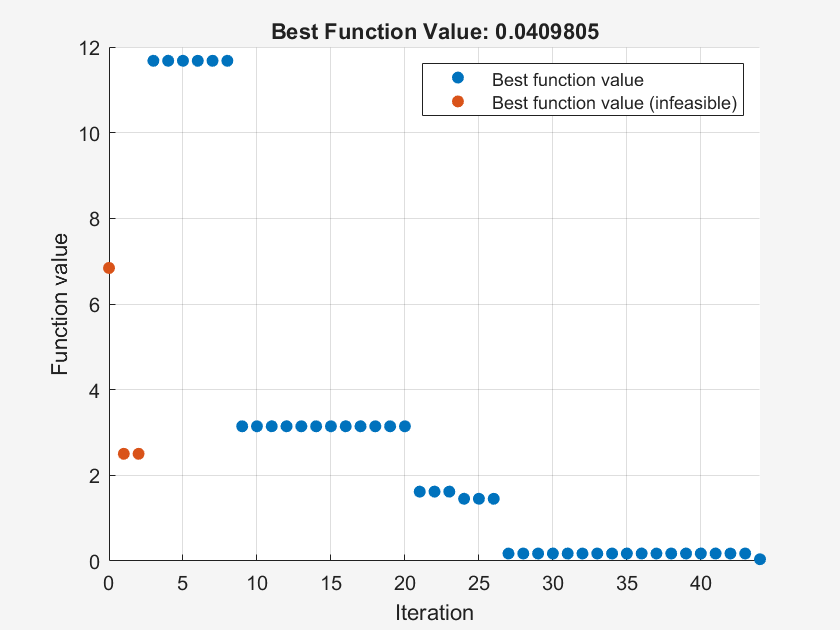

surrogateopt stopped because the objective function value reached 'options.ObjectiveLimit'.


[sol,fval,flag,output] = surrogateopt(myFun,lb,ub,1,options);

## View Optimal Solution

Display the optimal number of pipes

sol(1)

ans = 9

Display the optimal pipe diameter

sol(2)

ans = 0.0072

Plot the optimal solution and find the temperature mismatch.

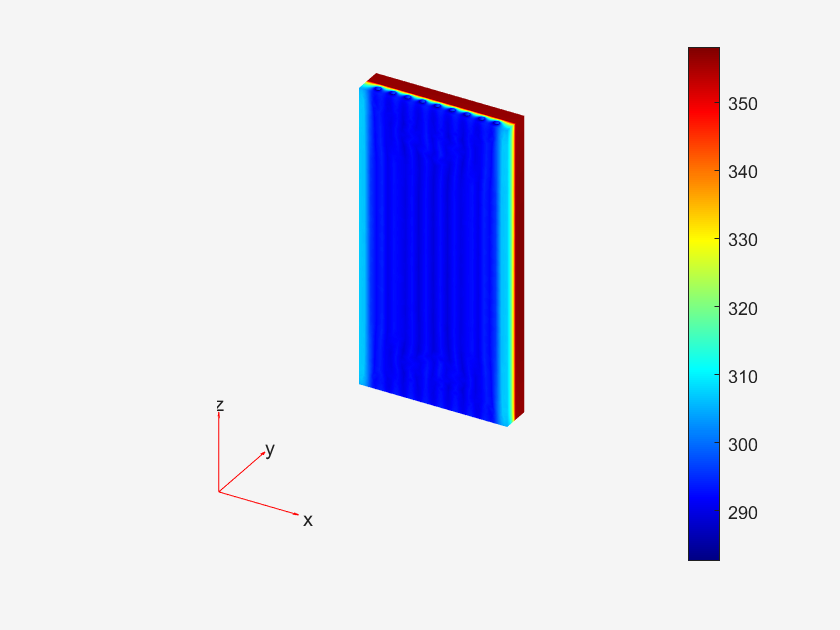

ans = 'Max temp on heat-producing block = 358.1090'

ModifyGeomRunFEAforOptim(sol,Tstar,1);

## Helper Functions

function ff = ModifyGeomRunFEAforOptim(x,T,displayResults)
    numPipes = x(1);
    if length(x) > 1
        D = x(2); % diameter of pipes (m)
    else 
        D = 0.015; % diameter of pipes (m)
    end

    L = 0.4; % length of pipes (m)
    % run helper function to modify geometry with these parameters
    gm3D = modifyGeometry(numPipes,D,L);

    % set up the model
    model = femodel("AnalysisType","thermalSteady","Geometry",gm3D);
    pipeFaces = setdiff(1:gm3D.NumFaces,1:11); % find which faces correspond to pipes for when we set BCs
    model = generateMesh(model,Hface={pipeFaces,D/5});

    % define material properties
    kBlockWithPipes = 0.5; % thermal conductivity of bottom block (W/(m*K))
    kBlockWithHeat = 80; % thermal conductivity of top block (W/(m*K))
    model.MaterialProperties(1) = materialProperties("ThermalConductivity",kBlockWithPipes); % block with pipes
    model.MaterialProperties(2) = materialProperties("ThermalConductivity",kBlockWithHeat); % block producing heat
    
    % Set Heat Load in the top block
    powerWattage = 0.5E3; % Power (W)
    volCell2 = 0.02*0.2*0.4; % Volume (m^3)
    heatSource = powerWattage/volCell2; % Heat source (W/m^3)
    model.CellLoad(2) = cellLoad("Heat",heatSource);

    % Compute heat transfer coefficient for convective BC
    LD_ratio = D/L; % ratio of diameter to length
    m_dot = 0.02; % mass flow rate (kg/s)
    mu = 0.001002; % dynamic viscosity (kg/(m*s)) of water at 20C
    Re = (4*m_dot)/(pi*D*mu); % Reynolds number
    Pr = 7.2; % Prandtl number of water at 20C
    if Re >= 10000
        Nu = 0.023*Re^0.8*Pr^0.4; % use Dittus-Boelter equation for high Re
    else
        Nu = 3.66; % else assume Nu constant
    end
    k = 0.598; % thermal conductivity of water at 20 C (W/(m*K))
    htc = (Nu*k)/D; % heat transfer coefficient

    % Natural convection to ambient
    model.FaceLoad(1:11) = faceLoad("ConvectionCoefficient",20,"AmbientTemperature",298.15); % free heat transfer coefficient of air, room temperature
    % Forced convection of chilled water in pipe
    model.FaceLoad(pipeFaces) = faceLoad("ConvectionCoefficient",htc,"AmbientTemperature",278.15); % forced convection coefficient of water, temperature of the water

    % Solve
    R = solve(model);
    blockNodes = findNodes(model.Mesh,"region","Cell",2);
    Tmax = max(R.Temperature(blockNodes));

    % Evaluate objective
    ff.Fval = abs(T-Tmax);

    % Evaluate constraints
    ff.Ineq = Tmax-T;

    if displayResults
        pdegplot(model);
        pdeplot3D(R.Mesh,ColorMapData=R.Temperature);
        sprintf('Max temp on heat-producing block = %0.4f', Tmax)
    end
end

function gm3D = modifyGeometry(numPipes,pipeDiameter,pipeLength)
    W = 0.2; % Cooling plate width (m)
    edgeGap = W*0.1;
    
    % First create 2D geometry
    R1 = [3; 4; 0; W; W; 0; 0; 0; 0.02; 0.02]; % create bottom rectangle
    R2 = [3; 4; 0; W; W; 0; 0.02; 0.02; 0.04; 0.04]; % create top rectangle
    Ci = zeros(size(R1,1),numPipes); % create circles for pipes
    Ci(1,:) = 1;
    Ci(2,:) = linspace(edgeGap, W-edgeGap, numPipes);
    Ci(3,:) = 0.01;
    Ci(4,:) = pipeDiameter/2;
    
    gdm = [R1,R2,Ci];
    sf = join(["(R1+R2)","C"+string(1:numPipes)],"-");
    ns = char(["R1"; "R2"; "C"+string(1:numPipes)']);
    g = decsg(gdm,sf,ns');
    gm2D = fegeometry(g);

    % extrude by length to create 3D geometry
    gm3D = extrude(gm2D,pipeLength);
end